% PROBLEM 3

% Clear workspace
close all
clear
clc

% Define the system matrices
Ap = [0 1; 0 0];
Bp = [0; 1];
Dp = [0 0; 1 0];
Cp = [0 1; 0 0];
By = [0; 1];
Dy = [0 0; 0 0];
Mp = [1 0];
Dz = [0 1];

% Lumped system matrices
A = Ap;
B = [Dp Bp];
C = [Cp; Mp];
D = [Dy By; Dz 0]

D =      0     0     0
     0     0     1
     0     1     0



% State-space system
Sol = ss(A, B, C, D)

Sol =
 
  A = 
       x1  x2
   x1   0   1
   x2   0   0
 
  B = 
       u1  u2  u3
   x1   0   0   0
   x2   1   0   1
 
  C = 
       x1  x2
   y1   0   1
   y2   0   0
   y3   1   0
 
  D = 
       u1  u2  u3
   y1   0   0   0
   y2   0   0   1
   y3   0   1   0
 
Continuous-time state-space model.


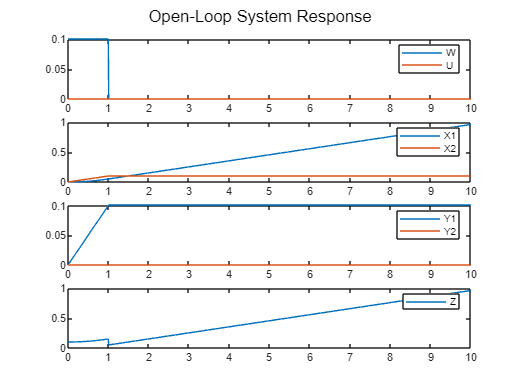

% sys_openloop = ss(Ap, Dp, Cp, 0)

% Define the lumped (disturbance + control) input
t = 0:0.01:10;
w_amplitude = 0.1;
w_duration = 1;
w_pulse = w_amplitude * (t >= 0 & t <= w_duration);
u = zeros(size(w_pulse));
w = [w_pulse; w_pulse; u];
% w = [w_pulse; w_pulse];

% Simulate the open-loop system response
[y_ol, t_out, x_ol] = lsim(Sol, w', t);
% [y_ol, t_out, x_ol] = lsim(Sol, w, t);

% Plot the results
figure;
sgtitle('Open-Loop System Response');
subplot(4, 1, 1);
plot(t, w(2, :), t, w(3, :));
legend('W', 'U');
subplot(4, 1, 2);
plot(t, x_ol(:, 1), t, x_ol(:, 2));
legend('X1', 'X2');
subplot(4, 1, 3);
plot(t, y_ol(:, 1), t, y_ol(:, 2));
legend('Y1', 'Y2');
subplot(4, 1, 4);
plot(t, y_ol(:, 3));
legend('Z');

% H-infinity LMI
S = ltisys(A, B, C, D);
[gopt, G] = hinflmi(S,[1 1])


 Minimization of gamma:

 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1
     2                   4.331487
     3                   2.480378
     4                   2.094585
     5                   1.984537
     6                   1.984537
     7                   1.891906
     8                   1.891906
***                 new lower bound:     0.208335
     9                   1.693528
    10                   1.693528
***                 new lower bound:     0.773250
    11                   1.636185
***                 new lower bound:     1.240010
    12                   1.636185
***                 new lower bound:     1.567929
    13                   1.622326
    14                   1.620133
***                 new lower bound:     1.604742

 Result:  feasible solution of required accuracy
          best objective value:     1.620133
          guaranteed relative accuracy:  9.50e-03
          f-ra

gopt = 1.6197

G =    -2.0572    1.5998    1.0000
    2.0785   -1.6165         0
         0         0      -Inf



% Controller matrices
disp('H∞ controller:')

H∞ controller:


[Ac, Bc, Cc, Dc] = ltiss(G)

Ac = -2.0572

Bc = 1.5998

Cc = 2.0785

Dc = -1.6165

% Closed-loop system matrices
disp('Closed-loop system:')

Closed-loop system:


Acl = [Ap+Bp*Dc*Mp, Bp*Cc; Bc*Mp, Ac]

Acl =          0    1.0000         0
   -1.6165         0    2.0785
    1.5998         0   -2.0572


Bcl = [Dp+Bp*Dc*Dz; Bc*Dz]

Bcl =          0         0
    1.0000   -1.6165
         0    1.5998


Ccl = [Cp+By*Dc*Mp, By*Cc]

Ccl =          0    1.0000         0
   -1.6165         0    2.0785


Dcl = Dy+By*Dc*Dz

Dcl =          0         0
         0   -1.6165



% Closed-loop system
Scl = ss(Acl, Bcl, Ccl, Dcl);
% Scl = slft(S, G);

% Verification
disp('H∞ norm:')

H∞ norm:


hinf_norm = hinfnorm(Scl)

hinf_norm = 1.6185

% hinf_norm = norminf(Scl)
disp('Closed-loop poles:')

Closed-loop poles:


eig_Acl = eig(Acl)

eig_Acl =   -1.0285 + 0.7471i
  -1.0285 - 0.7471i
  -0.0002 + 0.0000i


if((abs(gopt-hinf_norm) <= 0.1) && all(real(eig_Acl) < 0.0))
    disp('Verification of H∞ norm and pole location constraints successful!')
else
    disp('Verification of H∞ norm and pole location constraints failed!')
end

Verification of H∞ norm and pole location constraints successful!


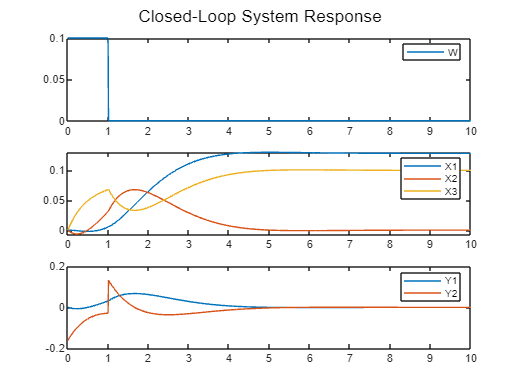

% Define the lumped (disturbance + control) input
t = 0:0.01:10;
w_amplitude = 0.1;
w_duration = 1;
w_pulse = w_amplitude * (t >= 0 & t <= w_duration);
u = zeros(size(w_pulse));
w = [w_pulse; w_pulse];

% Simulate the closed-loop system response
[y_cl, t_out, x_cl] = lsim(Scl, w', t);

% Plot the results
figure;
sgtitle('Closed-Loop System Response');
subplot(3, 1, 1);
plot(t, w(2, :));
legend('W');
subplot(3, 1, 2);
plot(t, x_cl(:, 1), t, x_cl(:, 2), t, x_cl(:, 3));
legend('X1', 'X2', 'X3');
subplot(3, 1, 3);
plot(t, y_cl(:, 1), t, y_cl(:, 2));
legend('Y1', 'Y2');